# 2 DoF Platform

Author: Emerson Kaneda

clc
clear all
close all
data = readtable("Mobile\droneLanding and takeoff");
FontSize = 30;

startIndex = 55*100;
endIndex = 85*100;

pitch = data.Pitch(startIndex:endIndex);
roll = data.Roll(startIndex:endIndex);
pitch_set_point = data.Pitch_set_point(startIndex:endIndex);
roll_set_point = data.Roll_set_point(startIndex:endIndex);

time = (0:length(pitch)-1) * 0.01; % 0.01 segundos = 10 ms

start_time = 0;

erro_pitch = pitch_set_point - pitch;
ME_p = mean(erro_pitch)            

ME_p = -0.1196

RMSE_p = sqrt(mean(erro_pitch.^2))       

RMSE_p = 0.5607


erro_roll= roll_set_point - roll;
ME_r = mean(erro_roll)                   

ME_r = -0.2042

RMSE_r = sqrt(mean(erro_roll.^2))

RMSE_r = 1.1894

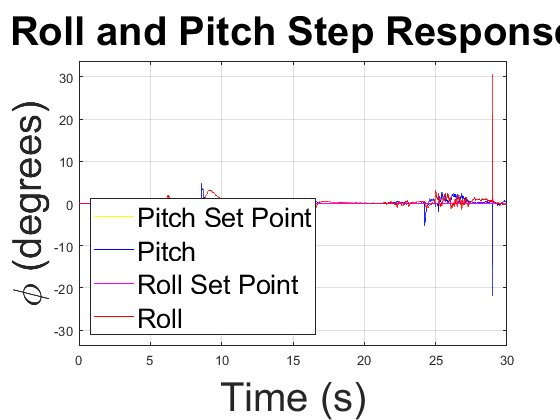


figure;
plot(time, pitch_set_point, 'y', 'DisplayName', 'Pitch Set Point');
hold on;
plot(time, pitch, 'b', 'DisplayName', 'Pitch');
plot(time, roll_set_point, 'm', 'DisplayName', 'Roll Set Point');
plot(time, roll, 'r', 'DisplayName', 'Roll');
hold off;

% Adicionar título e legendas
title('Roll and Pitch Step Response','FontSize', FontSize);
xlabel('Time (s)','FontSize', FontSize);
ylabel({'\phi (degrees)'},'FontSize', FontSize);
legend('show', 'Location', 'southwest','FontSize', 20);
% legend('show', 'Location', 'southwest','FontSize', 20);
grid on;

xlim([start_time, time(end)]);
% Exibir o gráfico
ylim([-max(max(abs([pitch; roll; pitch_set_point; roll_set_point])))*1.1, ...
    max(max(abs([pitch; roll; pitch_set_point; roll_set_point])))*1.1]);

highlight_time = 47.21; % Tempo em segundos a ser destacado
highlight_roll = roll(find(time >= highlight_time, 1)); % Valor de pitch nesse tempo
hold on;
% plot(highlight_time, highlight_roll, 'ro', 'MarkerSize', 30, 'LineWidth', 2,"DisplayName","Mechanical Noise","Color","k"); % Destacar o ponto com um círculo
hold off;


% Definição das constantes
L1 = 70;
L2 = 240;
% hCentral = sqrt(L2^2 - L1^2)
hCentral = 215

hCentral = 215

d = 210;

% Definição do intervalo de theta
theta = -90:1:90;
% Cálculo de h
h = L1 * sind(theta) + sqrt(L2^2 - (L1* cosd(theta)).^2)

h =   170.0000  170.0076  170.0302  170.0680  170.1208  170.1888  170.2719  170.3701  170.4834  170.6119  170.7554  170.9141  171.0880  171.2770  171.4811  171.7004  171.9348  172.1845  172.4492  172.7292  173.0244  173.3347  173.6603  174.0011  174.3570  174.7282  175.1146  175.5162  175.9331  176.3651  176.8124  177.2749  177.7527  178.2456  178.7537  179.2771  179.8156  180.3693  180.9382  181.5222  182.1213  182.7356  183.3649  184.0092  184.6686  185.3429  186.0322  186.7363  187.4553  188.1891


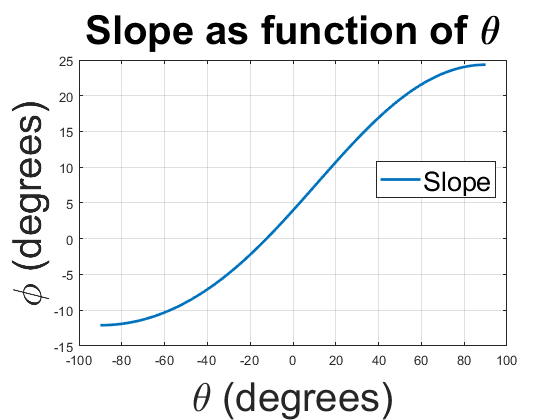

slope = atand((h - hCentral)/d);


% Plot do gráfico
figure;
plot(theta, slope, 'LineWidth', 2);
title('Slope as function of \theta','FontSize', FontSize);
xlabel('\theta (degrees)','FontSize', FontSize);
ylabel('\phi (degrees)','FontSize', FontSize);
legend('Slope ', 'Location', 'best','FontSize', 20);
grid on;

% Carregar os dados
pitch = data.Pitch;
roll = data.Roll;
pitch_set_point = data.Pitch_set_point;
roll_set_point = data.Roll_set_point;

% Tempo entre amostras
dt = 0.01; % Intervalo de tempo entre as amostras em segundos
time = 0:dt:dt*(length(pitch)-1);

% Ignorar dados antes de 43 segundos
start_time = 43;
start_idx = find(time >= start_time, 1);

steady_state_time = 5; % em segundos
steady_state_idx = find(time >= steady_state_time, 1);

pitch = pitch(start_idx:end);
roll = roll(start_idx:end);
pitch_set_point = pitch_set_point(start_idx:end);
roll_set_point = roll_set_point(start_idx:end);
time = time(start_idx:end) - start_time;

% Calcular parâmetros para pitch
[tr_pitch, ts_pitch, type_pitch, ess_pitch] = analyze_response(pitch, pitch_set_point, time, 0.02, steady_state_idx);

% Calcular parâmetros para roll
[tr_roll, ts_roll, type_roll, ess_roll] = analyze_response(roll, roll_set_point, time, 0.02, steady_state_idx);

% Exibir resultados
fprintf('Pitch - Tempo de Subida: %.2f s\n', tr_pitch);

Pitch - Tempo de Subida: 0.00 s


fprintf('Pitch - Tempo de Assentamento: %.2f s\n', ts_pitch);

Pitch - Tempo de Assentamento: 54.40 s


fprintf('Pitch - Tipo de Amortecimento: %s\n', type_pitch);

Pitch - Tipo de Amortecimento: Subamortecido (Under-damped)


fprintf('Pitch - Erro em Regime Permanente: %.4f\n', ess_pitch);

Pitch - Erro em Regime Permanente: 0.1977



fprintf('Roll - Tempo de Subida: %.2f s\n', tr_roll);

Roll - Tempo de Subida: 0.00 s


fprintf('Roll - Tempo de Assentamento: %.2f s\n', ts_roll);

Roll - Tempo de Assentamento: 55.25 s


fprintf('Roll - Tipo de Amortecimento: %s\n', type_roll);

Roll - Tipo de Amortecimento: Subamortecido (Under-damped)


fprintf('Roll - Erro em Regime Permanente: %.4f\n', ess_roll);

Roll - Erro em Regime Permanente: 0.3221


function [tr, ts, type, ess] = analyze_response(response, set_point, time, tol, ss_idx)
    % Normalizar resposta
    norm_response = response - set_point(1);
    norm_response = norm_response / (set_point(end) - set_point(1));

    % Tempo de subida (10% a 90%)
    idx_10 = find(norm_response >= 0.1, 1);
    idx_90 = find(norm_response >= 0.9, 1);
    tr = time(idx_90) - time(idx_10);

    % Tempo de assentamento
    final_value = set_point(end);
    idx_ts = find(abs(response - final_value) <= tol*abs(final_value), 1, 'last');
    ts = time(idx_ts);

    % Tipo de amortecimento
    overshoot = max(response) - final_value;
    if overshoot > tol * abs(final_value)
        type = 'Subamortecido (Under-damped)';
    elseif overshoot < tol * abs(final_value) && overshoot > 0
        type = 'Superamortecido (Over-damped)';
    else
        type = 'Criticamente Amortecido (Critically Damped)';
    end

    % Erro em regime permanente
    ess = abs(response(ss_idx:end) - final_value);
    ess = mean(ess); % Média do erro após o tempo de regime permanente
end